% 文件读取
demo_path = 'E:\学习资料\大三上\信号处理\training2017\training2017\demo\Normal';
heading_path = fullfile(demo_path, 'A00001.hea');
signal_path = fullfile(demo_path, 'A00001.mat');
fid = fopen(heading_path,'r');
tmp1 = fgetl(fid);
tmp2 = fgetl(fid);
info1 = sscanf(tmp1, '%*s %d %d %d',[1,3]);
info2 = sscanf(tmp2, '%*s %d %d %d',[1,6]);
Fs = 300;  % 采样频率300Hz
N = info1(3);  % 采样点数
gain = info2(3);  % 每mV对应点数
zerovalue = info2(5);  % 信号零点位置
t = N / Fs;  % 信号持续时间/s
time = 0:(1/Fs):(t-1/Fs);  % 时间数组
n = 0:N-1;  % 点数数组

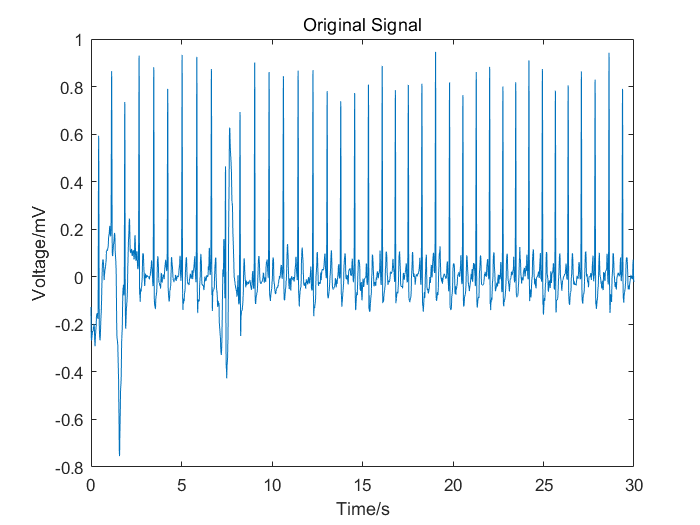

% 绘制原始信号
signal_struct = load(signal_path);  % 返回一个struct
signal_val = signal_struct.val(:);  % 获取信号所有取值
signal_val_zerocenter = signal_val - zerovalue;  % 将零点移到0值上
voltage = signal_val_zerocenter / gain;  % 获取电压值
figure('Name', 'Original Signal', 'NumberTitle', 'off');
plot(time, voltage);
xlabel('Time/s');
ylabel('Voltage/mV');
title('Original Signal');

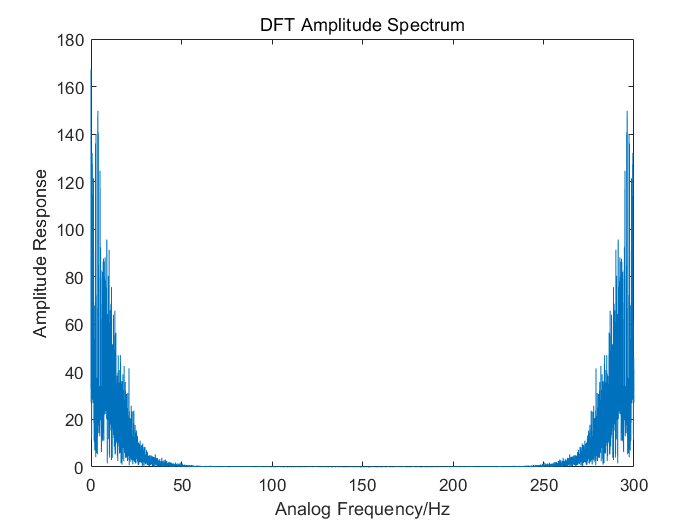

% 绘制FFT结果（幅频特性）
y = fft(voltage);
f = Fs / N * (0 : N - 1);
figure('Name', 'DFT Amplitude Spectrum', 'NumberTitle', 'off');
plot(f, abs(y));
xlabel('Analog Frequency/Hz');
ylabel('Amplitude Response');
title('DFT Amplitude Spectrum');

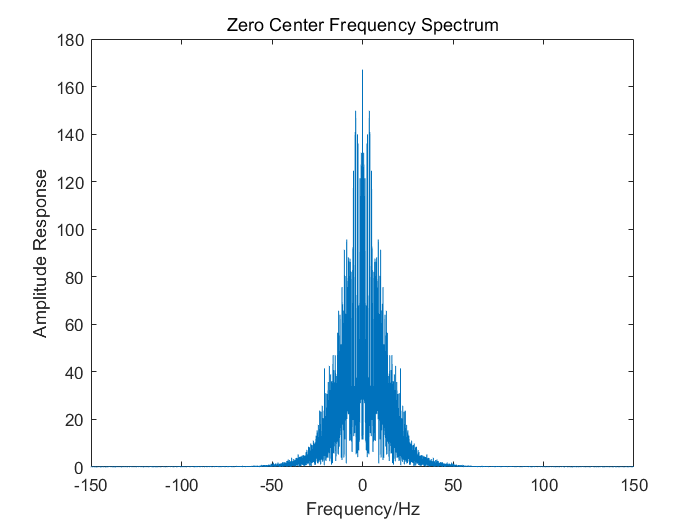

% 绘制以0为中心的幅频特性曲线与功率谱
y_center = fftshift(y);
powershift = abs(y_center) .^2 / N;
f_center = Fs / N * (- N / 2 : N / 2 - 1);
figure('Name', 'Zero Center Frequency Spectrum', 'NumberTitle', 'off');
plot(f_center, abs(y_center));
xlabel('Frequency/Hz');
ylabel('Amplitude Response');
title('Zero Center Frequency Spectrum');

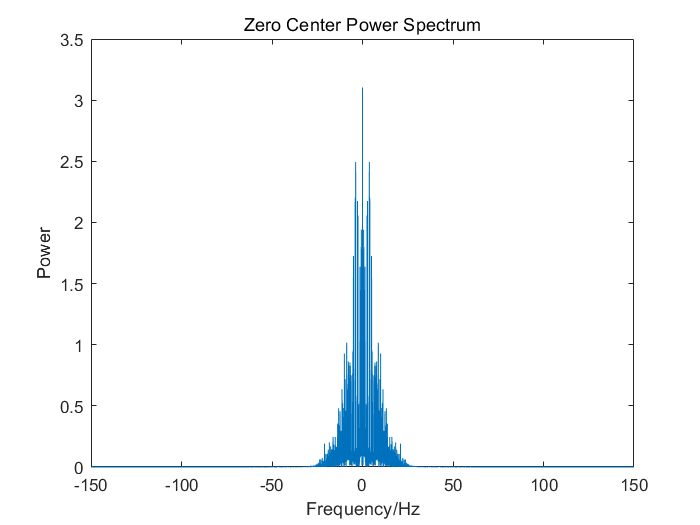


figure('Name', 'Zero Center Power Spectrum', 'NumberTitle', 'off');
plot(f_center, powershift);
xlabel('Frequency/Hz');
ylabel('Power');
title('Zero Center Power Spectrum');

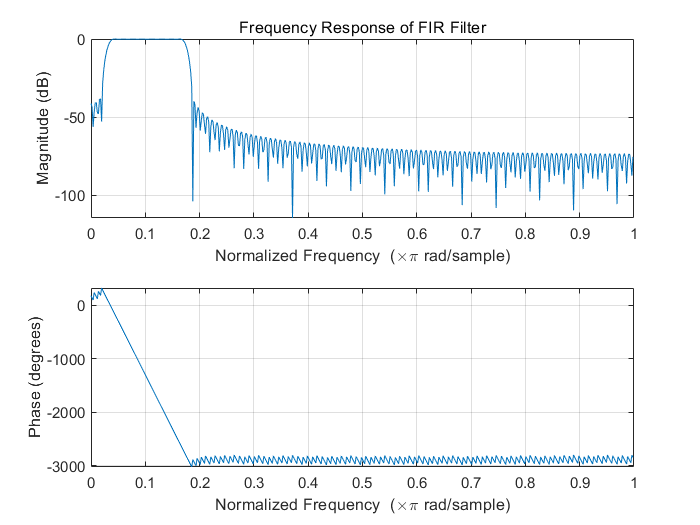

% 设计kaiser窗FIR滤波器
fcuts = [3 6 25 28];  % 3Hz过渡带
mags = [0 1 0];  % 通带内放大倍数1，阻带内放大倍数0
devs = [0.05 0.01 0.05];

[n_order, Wn, beta, ftype] = kaiserord(fcuts, mags, devs, Fs);
hh = fir1(n_order, Wn, ftype, kaiser(n_order + 1, beta), 'noscale');

figure('Name', 'Frequency Response of FIR Filter', 'NumberTitle', 'off');
freqz(hh);
title('Frequency Response of FIR Filter');


voltage_filtered = filter(hh, 1, voltage);

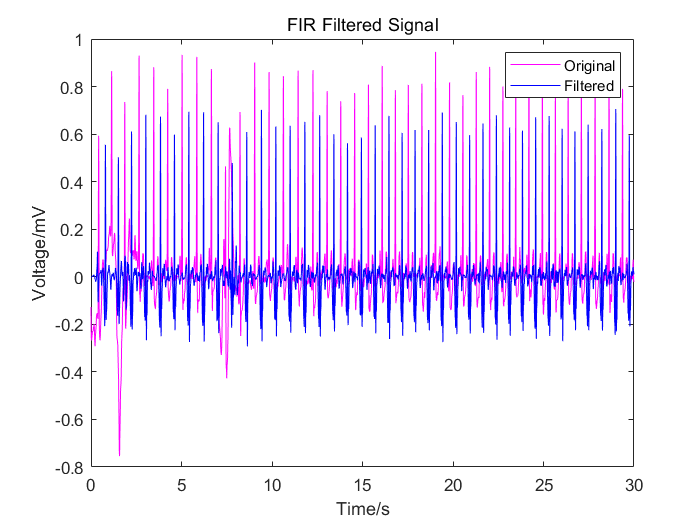

% 绘制滤波后的图像，会产生时域延迟
figure('Name', 'FIR Filtered', 'NumberTitle', 'off');
plot(time, voltage, 'm');
hold on;
plot(time, voltage_filtered, 'b');
xlabel('Time/s');
ylabel('Voltage/mV');
legend('Original', 'Filtered');
title('FIR Filtered Signal');

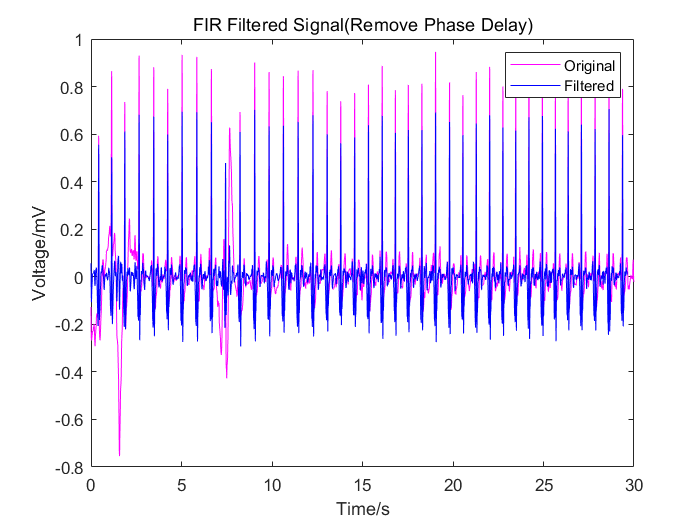

% 消除时域延迟，FIR滤波器会导致信号有效长度损失
n1 = n_order / 2;
voltage_filtered1 = voltage_filtered(n1: 1: end);
time1 = 0:1 / Fs:(t - n1 / Fs);
figure('Name', 'FIR Filtered(Remove Phase Delay)', 'NumberTitle', 'off');
plot(time, voltage, 'm');
hold on;
plot(time1, voltage_filtered1, 'b');
xlabel('Time/s');
ylabel('Voltage/mV');
legend('Original', 'Filtered');
title('FIR Filtered Signal(Remove Phase Delay)');

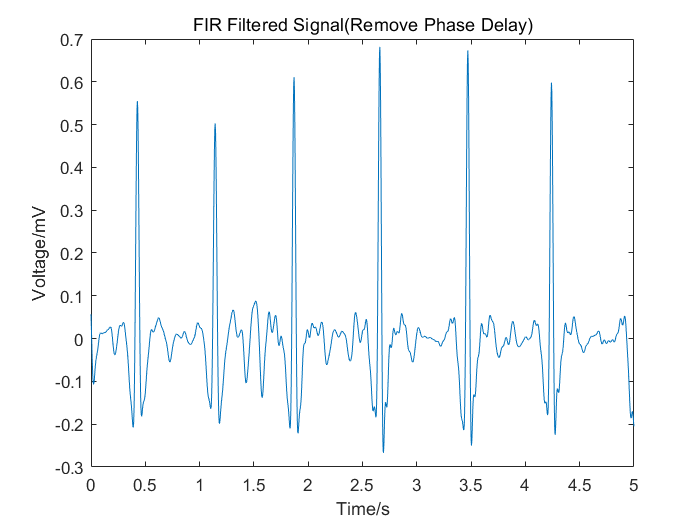

% 绘制细节
time_short = 0:1/Fs:5;
voltage_short = voltage_filtered(n1: 1: 1500 + n1);
figure('Name', 'FIR Filtered(Remove Phase Delay)', 'NumberTitle', 'off');
plot(time_short, voltage_short);
xlabel('Time/s');
ylabel('Voltage/mV');
title('FIR Filtered Signal(Remove Phase Delay)');